# Machine Learning Verification of Primate Eye Tracker

## Load

### 4 Variables Files, Where T1 is data throughout the manuscript. T2-T3 are additional tests under different conditions.

load T1_Processed_Smooth_Saccade_Capcoil.mat
load T2_Processed_Smooth_Capcoil.mat
load T3_Processed_Smooth_Saccade_Capcoil.mat

### Horizontal Smooth

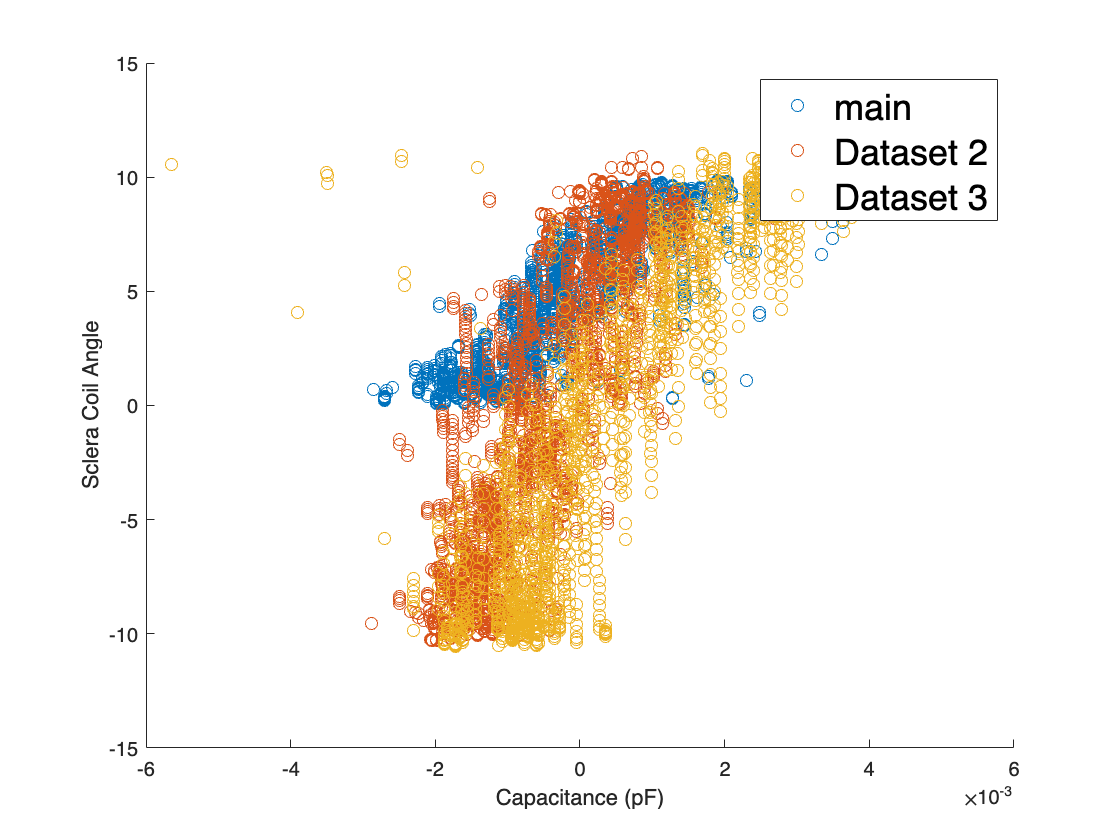

scatter(T1_Processed_HSMO_CAPCOIL(:,1),T1_Processed_HSMO_CAPCOIL(:,2)); hold on
scatter(T2_Processed_HSM_CAPCOIL(:,1),T2_Processed_HSM_CAPCOIL(:,2)); hold on
scatter(T3_Processed_HSM1_CAPCOIL(:,1),T3_Processed_HSM1_CAPCOIL(:,2)); hold off

xlabel("Capacitance (pF)"); xlim([-0.006 0.006])
ylabel("Sclera Coil Angle"); ylim([-15 15])
legend("main","Dataset 2", "Dataset 3",fontsize = 18)

### Trim to range

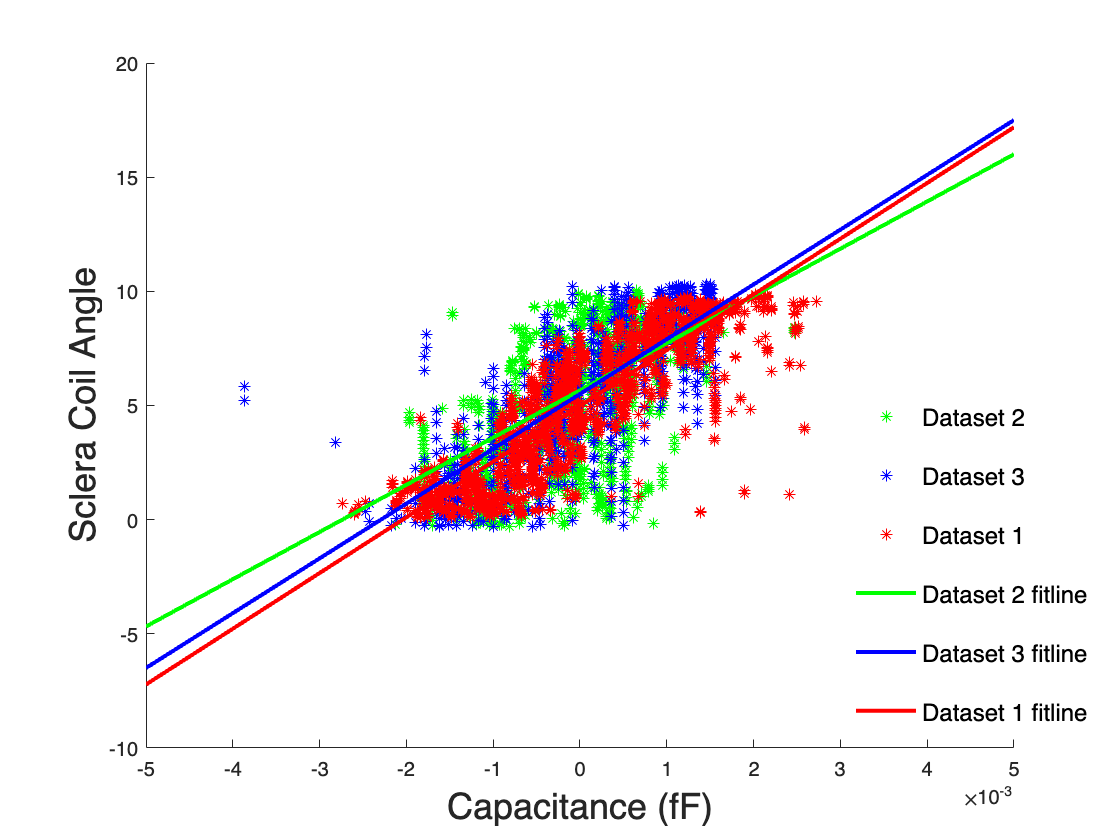

hsm1 = limitData(T1_Processed_HSMO_CAPCOIL, -0.3, 10.3, -3e-3, 3e-3);
hsm2 = limitData(T2_Processed_HSM_CAPCOIL, -0.3, 10.3, -3e-3, 3e-3);
hsm3 = limitData(T3_Processed_HSM1_CAPCOIL, -0.3, 10.3, -3e-3, 3e-3);

fitline1 = polyfit(hsm1(:,1),hsm1(:,2),1);
fitline2 = polyfit(hsm2(:,1),hsm2(:,2),1);
fitline3 = polyfit(hsm3(:,1),hsm3(:,2),1);

scatter(hsm2(:,1),hsm2(:,2),"g*"); hold on
scatter(hsm3(:,1),hsm3(:,2),"b*"); hold on
scatter(hsm1(:,1),hsm1(:,2),"r*"); hold on; 

fplot(@(x) fitline2(1)*x+fitline2(2),"g", LineWidth=2); hold on;
fplot(@(x) fitline3(1)*x+fitline3(2),"b", LineWidth=2); hold on;
fplot(@(x) fitline1(1)*x+fitline1(2),"r", LineWidth=2); hold off;

legend("Dataset 2", "Dataset 3","Dataset 1","Dataset 2 fitline",...
    "Dataset 3 fitline","Dataset 1 fitline",'box','off', fontsize = 12)
legend("Position", [0.72002,0.11098,0.29643,0.4369])
xlabel("Capacitance (fF)",fontsize = 18); 
ylabel("Sclera Coil Angle",fontsize = 18); xlim([-5e-3 5e-3])

rng(10)
[train1, test1] = partitionArray(hsm1,0.2);
[train2, test2] = partitionArray(hsm2,0.2);
[train3, test3] = partitionArray(hsm3,0.2);


train12 = [train1; train2]; tes12 = [test1; test2];
train13 = [train1; train3]; tes13 = [test1; test3];
train23 = [train2; train3]; tes23 = [test2; test3];
trainAll = [train1; train2; train3];testAll = [test1; test2; test3];

### Vertical Smooth

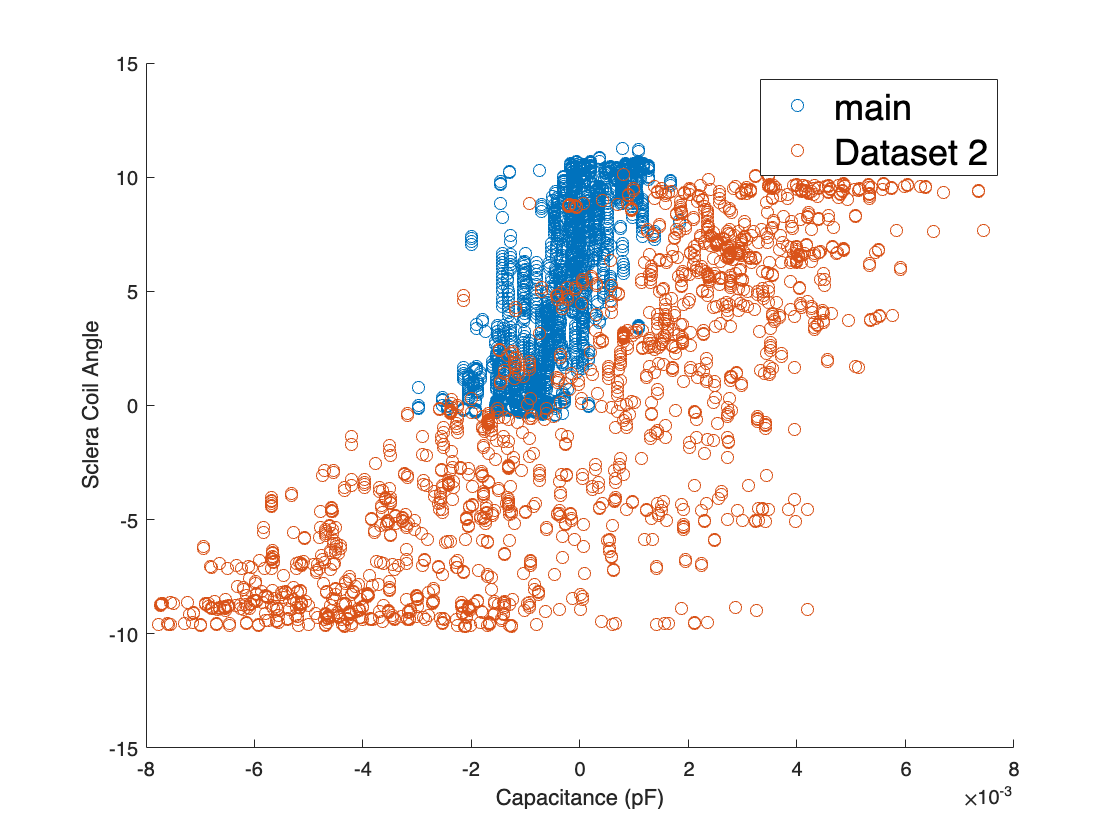

scatter(T1_Processed_VSMO_CAPCOIL(:,1),T1_Processed_VSMO_CAPCOIL(:,2)); hold on
scatter(T2_Processed_VSM_CAPCOIL(:,1),T2_Processed_VSM_CAPCOIL(:,2)); hold off

xlabel("Capacitance (pF)"); xlim([-0.008 0.008])
ylabel("Sclera Coil Angle"); ylim([-15 15])
legend("main","Dataset 2",fontsize = 18)

### Trim to range

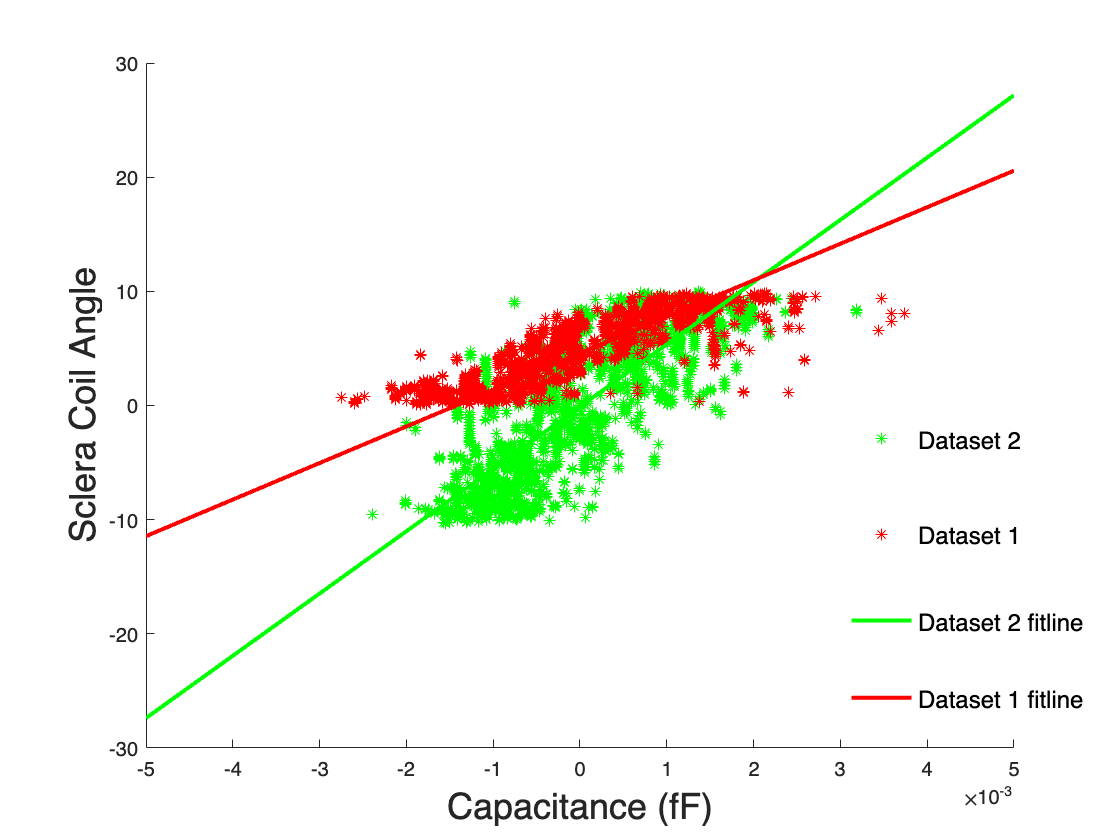

vsm1 = limitData(T1_Processed_VSMO_CAPCOIL, -10.3, 10.3, -6e-3, 6e-3);
vsm2 = limitData(T2_Processed_HSM_CAPCOIL, -10.3, 10.3, -6e-3, 6e-3);

fitline1 = polyfit(vsm1(:,1),vsm1(:,2),1);
fitline2 = polyfit(vsm2(:,1),vsm2(:,2),1);

scatter(vsm2(:,1),vsm2(:,2),"g*"); hold on
scatter(hsm1(:,1),hsm1(:,2),"r*"); hold on; 

fplot(@(x) fitline2(1)*x+fitline2(2),"g", LineWidth=2); hold on;
fplot(@(x) fitline1(1)*x+fitline1(2),"r", LineWidth=2); hold off;

legend("Dataset 2", "Dataset 1","Dataset 2 fitline",...
    "Dataset 1 fitline",'box','off', fontsize = 12)
legend("Position", [0.72002,0.11098,0.29643,0.4369])
xlabel("Capacitance (fF)",fontsize = 18); 
ylabel("Sclera Coil Angle",fontsize = 18); xlim([-5e-3 5e-3])

rng(10)
[trainv1, testv1] = partitionArray(vsm1,0.2);
[trainv2, testv2] = partitionArray(vsm2,0.2);

### Saccade

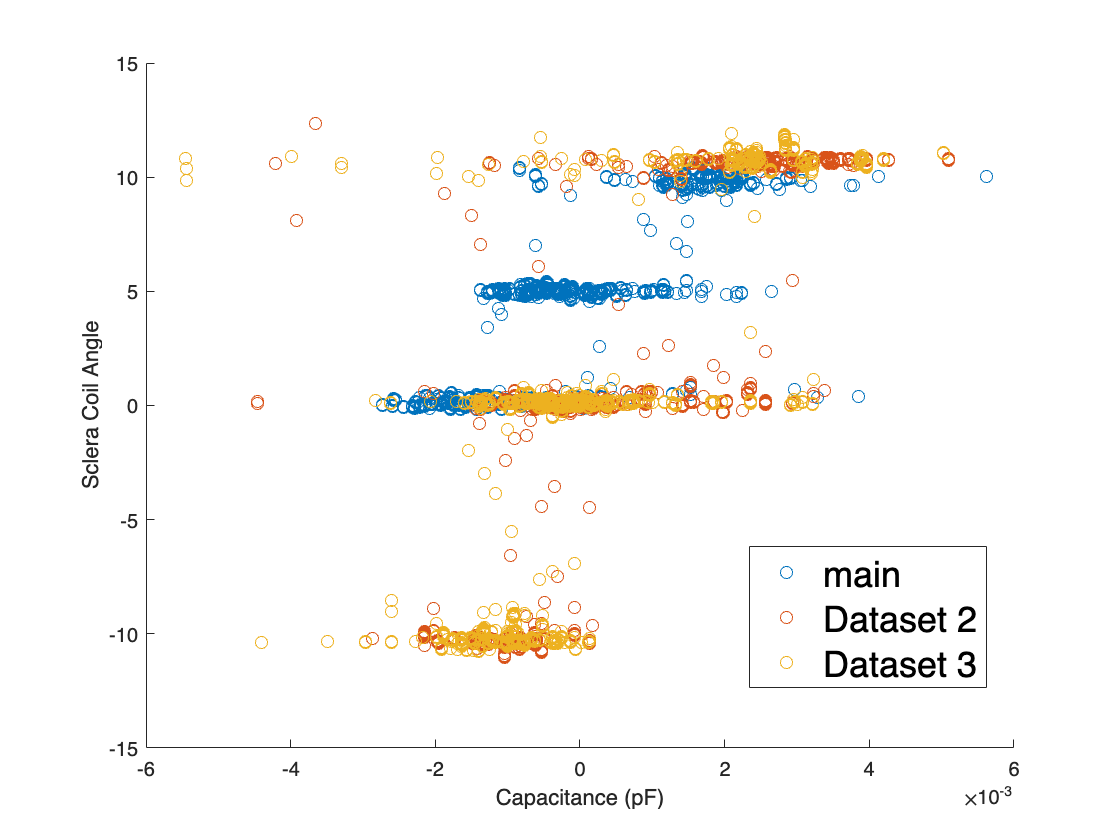

scatter(T1_Processed_HSAC_CAPCOIL(:,1),T1_Processed_HSAC_CAPCOIL(:,2)); hold on
scatter(T3_Processed_HSAC1_CAPCOIL(:,1),T3_Processed_HSAC1_CAPCOIL(:,2)); hold on
scatter(T3_Processed_HSAC2_CAPCOIL(:,1),T3_Processed_HSAC2_CAPCOIL(:,2)); hold off

xlabel("Capacitance (pF)"); xlim([-0.006 0.006])
ylabel("Sclera Coil Angle"); ylim([-15 15])
legend("main","Dataset 2", "Dataset 3",fontsize = 18)
legend("Position", [0.66862,0.18084,0.2125,0.16905])

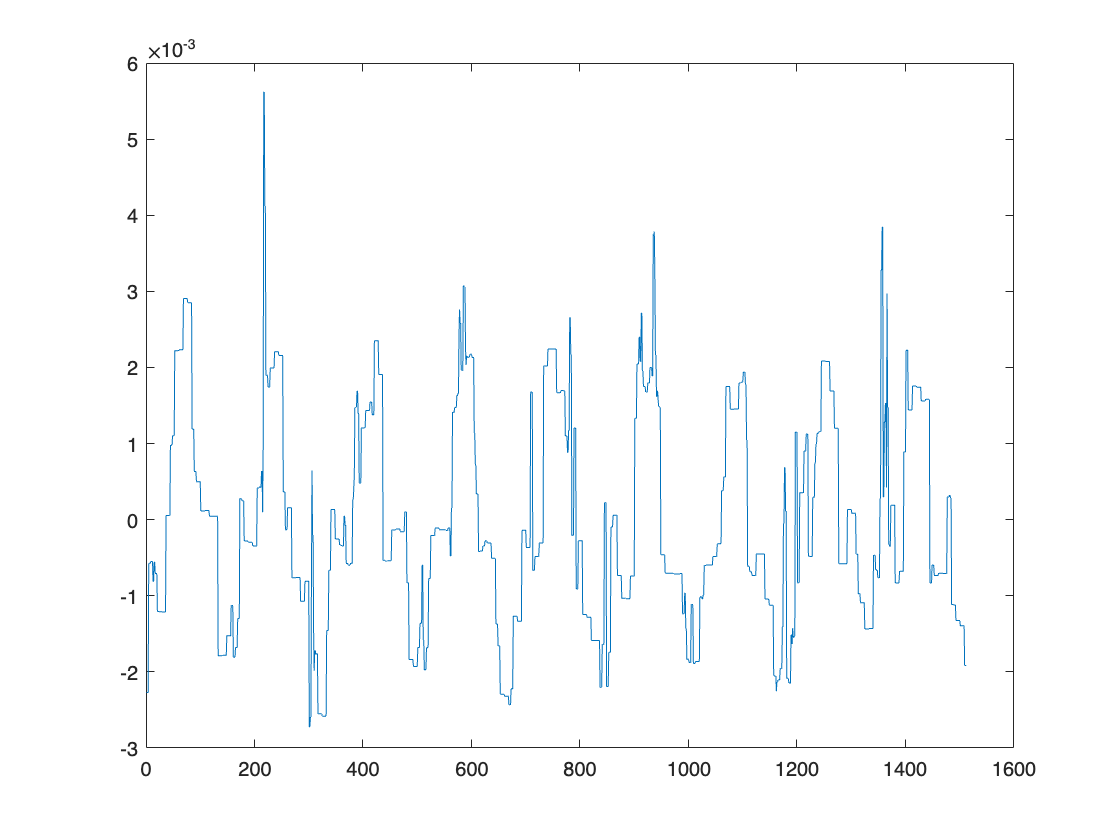

clf
plot(T1_Processed_HSAC_CAPCOIL(:,1));

### Trim to range

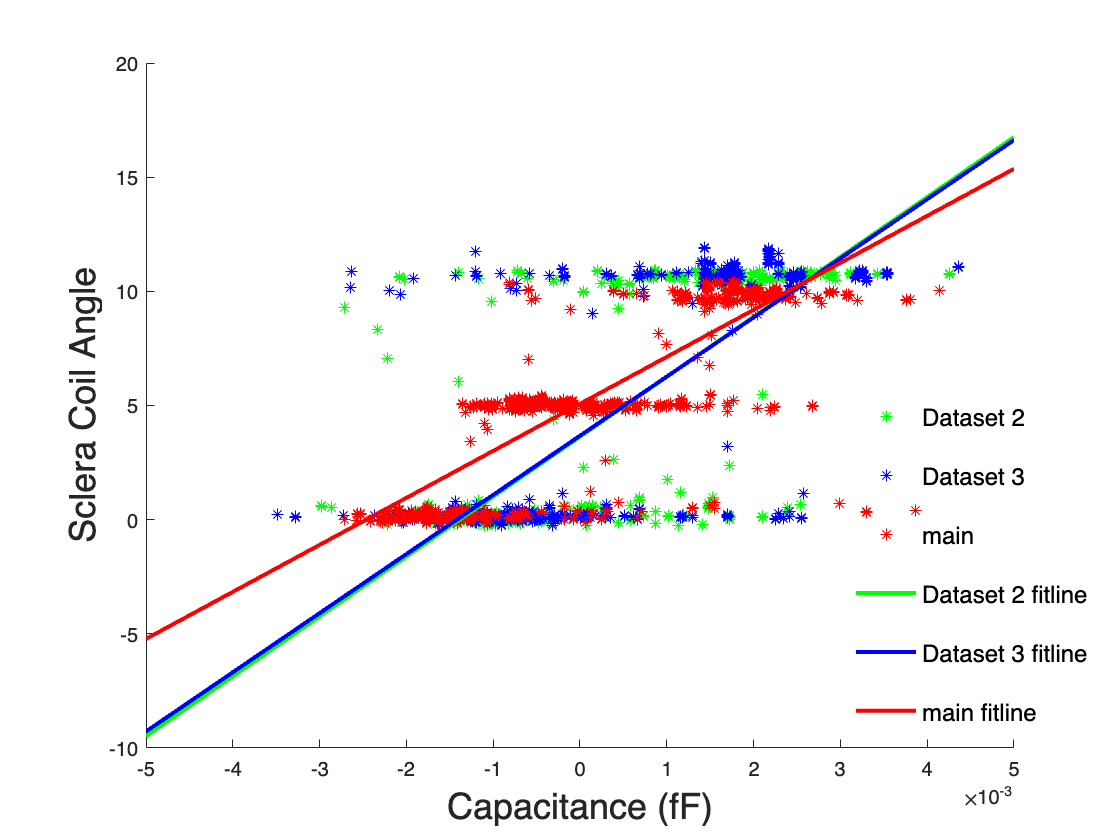

hsac1 = limitData(T1_Processed_HSAC_CAPCOIL, -0.3, 13.3, -3e-3, 6e-3);
hsac2 = limitData(T3_Processed_HSAC1_CAPCOIL, -0.3, 13.3, -3e-3, 6e-3);
hsac3 = limitData(T3_Processed_HSAC2_CAPCOIL, -0.3, 13.3, -3e-3, 6e-3);

fitline1 = polyfit(hsac1(:,1),hsac1(:,2),1);
fitline2 = polyfit(hsac2(:,1),hsac2(:,2),1);
fitline3 = polyfit(hsac3(:,1),hsac3(:,2),1);

scatter(hsac2(:,1),hsac2(:,2),"g*"); hold on
scatter(hsac3(:,1),hsac3(:,2),"b*"); hold on
scatter(hsac1(:,1),hsac1(:,2),"r*"); hold on; 

fplot(@(x) fitline2(1)*x+fitline2(2),"g", LineWidth=2); hold on;
fplot(@(x) fitline3(1)*x+fitline3(2),"b", LineWidth=2); hold on;
fplot(@(x) fitline1(1)*x+fitline1(2),"r", LineWidth=2); hold off;

legend("Dataset 2", "Dataset 3","main","Dataset 2 fitline",...
    "Dataset 3 fitline","main fitline",'box','off', fontsize = 12)
legend("Position", [0.72002,0.11098,0.29643,0.4369])
xlabel("Capacitance (fF)",fontsize = 18); 
ylabel("Sclera Coil Angle",fontsize = 18); xlim([-5e-3 5e-3])

[trainc3, testc3] = partitionArray(hsac2,0.2);

function dataout = limitData(datain, angle_low, angle_high, cap_low, cap_high)
    angleMask = (datain(:, 2) >= angle_low) & (datain(:, 2) <= angle_high);
    capMask = (datain(:, 1) >= cap_low) & (datain(:, 1) <= cap_high);
    dataout = datain(angleMask & capMask, :);
    dataout(:,1) = detrend(dataout(:,1),0); % Remove 0-th order constant bias
end

function [Training, Testing] = partitionArray(inArray, fraction)
    if (fraction < 0.01 || fraction > 0.99)
        fraction = 0.2; disp("Illegal fraction. Reset to 0.2.");
    end
    inArray = inArray(randperm(size(inArray,1)),:);
    c = cvpartition(size(inArray,1),'Holdout',fraction);
    Train_Index = training(c);
    Test_Index = test(c);
    Training = inArray(Train_Index,:);
    Testing = inArray(Test_Index,:);
end